
===== Stable System =====


Method        RHP    Stable


Routh         0      1


roots()       0      1


eig()         0      1



Runtime:


Routh : 1.662265e-05 s


roots : 2.183982e-05 s


eig   : 2.499969e-06 s


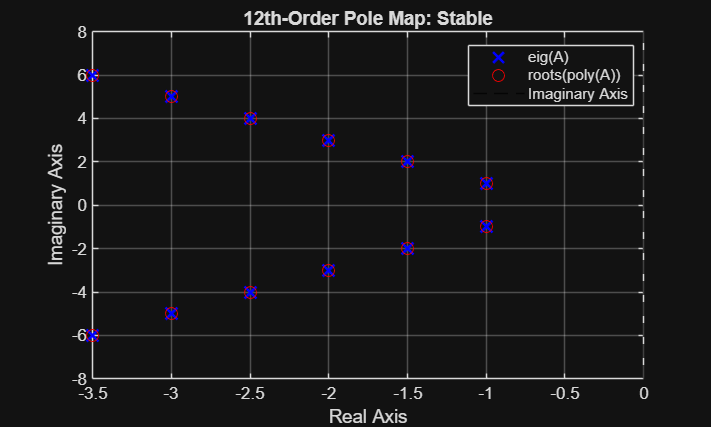


===== Unstable System =====


Method        RHP    Stable


Routh         2      0


roots()       2      0


eig()         2      0



Runtime:


Routh : 1.576430e-05 s


roots : 2.334088e-05 s


eig   : 2.239450e-06 s


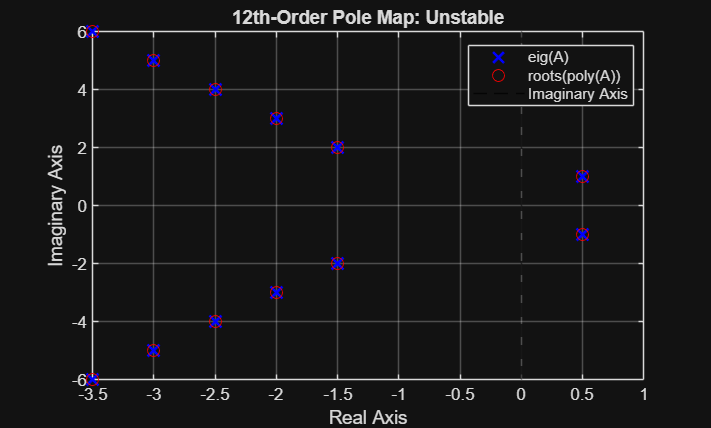

%% Experiment: 12th-Order System Stability
clear; clc; close all;


%% Step 1: Construct 12th-order state matrix

sigma = [1 1.5 2 2.5 3 3.5];
omega = [1 2 3 4 5 6];

A = zeros(12, 12);

for k = 1:6
    idx = 2*k-1 : 2*k;

    A(idx,idx) = [-sigma(k), -omega(k);
                   omega(k), -sigma(k)];
end

%% Step 2: Construct stable and unstable cases

A_stable = A;

A_unstable = A;
A_unstable(1:2,1:2) = [0.5 -1;
                       1   0.5];

systems = {A_stable, A_unstable};
names = {'Stable', 'Unstable'};

%% Step 3: Compare three methods

tol = 1e-8;

for k = 1:numel(systems)

    A = systems{k};
    coeff = poly(A);

    fprintf('\n===== %s System =====\n', names{k});

    % Method 1: Routh-Hurwitz
    [rhpRouth, stableRouth] = routhOptimized(coeff);

    % Method 2: Polynomial roots
    r = roots(coeff);
    rhpRoots = nnz(real(r) > tol);
    stableRoots = all(real(r) < -tol);

    % Method 3: State-space eigenvalues
    lambda = eig(A);
    rhpEig = nnz(real(lambda) > tol);
    stableEig = all(real(lambda) < -tol);

    fprintf('Method        RHP    Stable\n');
    fprintf('Routh         %d      %d\n', rhpRouth, stableRouth);
    fprintf('roots()       %d      %d\n', rhpRoots, stableRoots);
    fprintf('eig()         %d      %d\n', rhpEig, stableEig);

    % Verify consistency
    assert(rhpRouth == rhpEig, 'Routh RHP mismatch');
    assert(stableRouth == stableEig, 'Routh stability mismatch');
    assert(rhpRoots == rhpEig, 'Roots RHP mismatch');
    assert(stableRoots == stableEig, 'Roots stability mismatch');

    %% Step 4: Runtime benchmark

    tRouth = timeit(@() routhOptimized(coeff));
    tRoots = timeit(@() roots(coeff));
    tEig = timeit(@() eig(A));

    fprintf('\nRuntime:\n');
    fprintf('Routh : %.6e s\n', tRouth);
    fprintf('roots : %.6e s\n', tRoots);
    fprintf('eig   : %.6e s\n', tEig);

    %% Step 5: Pole visualization

    figure;
    plot(real(lambda), imag(lambda), 'bx', ...
        'MarkerSize', 10, 'LineWidth', 1.5);
    hold on;
    plot(real(r), imag(r), 'ro', ...
        'MarkerSize', 7);

    xline(0, 'k--');
    grid on;
    xlabel('Real Axis');
    ylabel('Imaginary Axis');
    title(['12th-Order Pole Map: ', names{k}]);
    legend('eig(A)', 'roots(poly(A))', ...
           'Imaginary Axis', 'Location', 'best');

end